# EXAMEN CALCUL NUMERIC 5 IUNIE 2024

# SET 2

# Bugnar Andreea - gr. 331

# PROBLEMA 3

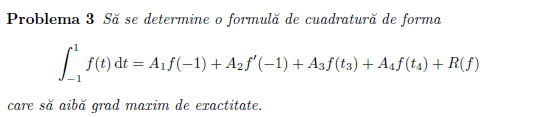

syms xi a1 a2 a3 a4 t3 t4 K Rest u
ec = sym(zeros(6, 1));
for k=1:6
    ec(k) = RR(@(t) t^(k-1), a1, a2, a3, a4, t3, t4) == 0
end

$$ec = \left(\begin{array}{c} 2-a_{3}-a_{4}-a_{1}=0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

$$ec = \left(\begin{array}{c} 2-a_{3}-a_{4}-a_{1}=0\\ a_{1}-a_{2}-a_{3}\,t_{3}-a_{4}\,t_{4}=0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

$$ec = \left(\begin{array}{c} 2-a_{3}-a_{4}-a_{1}=0\\ a_{1}-a_{2}-a_{3}\,t_{3}-a_{4}\,t_{4}=0\\ -a_{3}\,{t_{3}}^{2}-a_{4}\,{t_{4}}^{2}-a_{1}+2\,a_{2}+\frac{2}{3}=0\\ 0\\ 0\\ 0 \end{array}\right)$$

$$ec = \left(\begin{array}{c} 2-a_{3}-a_{4}-a_{1}=0\\ a_{1}-a_{2}-a_{3}\,t_{3}-a_{4}\,t_{4}=0\\ -a_{3}\,{t_{3}}^{2}-a_{4}\,{t_{4}}^{2}-a_{1}+2\,a_{2}+\frac{2}{3}=0\\ -a_{3}\,{t_{3}}^{3}-a_{4}\,{t_{4}}^{3}+a_{1}-3\,a_{2}=0\\ 0\\ 0 \end{array}\right)$$

$$ec = \left(\begin{array}{c} 2-a_{3}-a_{4}-a_{1}=0\\ a_{1}-a_{2}-a_{3}\,t_{3}-a_{4}\,t_{4}=0\\ -a_{3}\,{t_{3}}^{2}-a_{4}\,{t_{4}}^{2}-a_{1}+2\,a_{2}+\frac{2}{3}=0\\ -a_{3}\,{t_{3}}^{3}-a_{4}\,{t_{4}}^{3}+a_{1}-3\,a_{2}=0\\ -a_{3}\,{t_{3}}^{4}-a_{4}\,{t_{4}}^{4}-a_{1}+4\,a_{2}+\frac{2}{5}=0\\ 0 \end{array}\right)$$

$$ec = \left(\begin{array}{c} 2-a_{3}-a_{4}-a_{1}=0\\ a_{1}-a_{2}-a_{3}\,t_{3}-a_{4}\,t_{4}=0\\ -a_{3}\,{t_{3}}^{2}-a_{4}\,{t_{4}}^{2}-a_{1}+2\,a_{2}+\frac{2}{3}=0\\ -a_{3}\,{t_{3}}^{3}-a_{4}\,{t_{4}}^{3}+a_{1}-3\,a_{2}=0\\ -a_{3}\,{t_{3}}^{4}-a_{4}\,{t_{4}}^{4}-a_{1}+4\,a_{2}+\frac{2}{5}=0\\ -a_{3}\,{t_{3}}^{5}-a_{4}\,{t_{4}}^{5}+a_{1}-5\,a_{2}=0 \end{array}\right)$$


[a1, a2, a3, a4, t3, t4] = solve(ec, [a1, a2, a3, a4, t3, t4])

$$a1 = \left(\begin{array}{c} \frac{23}{54}\\ \frac{23}{54} \end{array}\right)$$

$$a2 = \left(\begin{array}{c} \frac{1}{18}\\ \frac{1}{18} \end{array}\right)$$

$$a3 = \left(\begin{array}{c} \frac{85}{108}-\frac{25\,\sqrt{10}}{432}\\ \frac{25\,\sqrt{10}}{432}+\frac{85}{108} \end{array}\right)$$

$$a4 = \left(\begin{array}{c} \frac{25\,\sqrt{10}}{432}+\frac{85}{108}\\ \frac{85}{108}-\frac{25\,\sqrt{10}}{432} \end{array}\right)$$

$$t3 = \left(\begin{array}{c} \frac{2\,\sqrt{10}}{15}+\frac{1}{3}\\ \frac{1}{3}-\frac{2\,\sqrt{10}}{15} \end{array}\right)$$

$$t4 = \left(\begin{array}{c} \frac{1}{3}-\frac{2\,\sqrt{10}}{15}\\ \frac{2\,\sqrt{10}}{15}+\frac{1}{3} \end{array}\right)$$

%incercam cu f(x)=t^6
(23/54)*(-1)^6 + (1/18)*6*(-1)^5 + (85/108 - 25*sqrt(10)/432)*(2*sqrt(10)/15 + 1/3)^6 +(25*sqrt(10)/432+85/108)*(1/3-2*sqrt(10)/15)^6  == factorial(6) % deci gradul maxim de exactitate este d=5?

ans = logical
   0


eval(a1(1)*(-1)^6 + a2(1)*6*(-1)^5 + a3(1)*t3(1)^6 + a4(1)*t4(1)^6) == factorial(6)

ans = logical
   0


syms u f(x) xi

g = @(x)piecewise(x >= u, (x - u)^5 / factorial(5), 0)

g = function_handle with value:
    @(x)piecewise(x>=u,(x-u)^5/factorial(5),0)



K = simplify(RR(g, a1(1), a2(1), a3(1), a4(1), t3(1), t4(1)))

$$K = \begin{array}{l} \left\{ \begin{array}{cl} 0 & \text{ if }u<-1\\ \frac{{\left(u+1\right)}^{4}}{432} & \text{ if }u\leq -1\\ 0 & \text{ if }u\notin \mathbb{R}\vee 1\leq u\\ \frac{{\left(u+1\right)}^{4}\,\left(9\,u^{2}-5\,u+1\right)}{6480} & \text{ if }u\in \left[-1,\frac{1}{3}-\sigma_{1}\right]\\ \sigma_{2}+\frac{\left(\frac{25\,\sqrt{10}}{432}-\frac{85}{108}\right)\,{\left(\sigma_{1}-u+\frac{1}{3}\right)}^{5}}{120} & \text{ if }u\in \left[-1,\sigma_{1}+\frac{1}{3}\right]\\ \sigma_{2} & \text{ if }u\in \left[-1,1\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\sqrt{10}}{15}\\ \sigma_{2}=\frac{{\left(u-1\right)}^{6}}{720} \end{array}$$

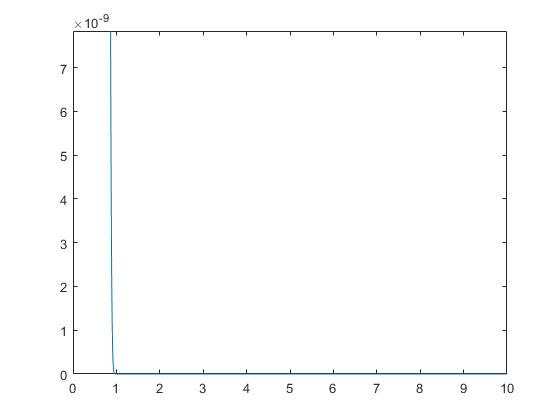

fplot(K,[0,10])


%din grafic rezulta ca nu isi schimba semnul, putem aplica corolarul

% Compute Rest1 using factorial and other operations
Rest = 1 / factorial(6) * simplify(RR(@(x) x^6, a1(1), a2(1), a3(1), a4(1), t3(1), t4(1))) * subs(diff(f(x), x, 6), x, xi)

$$Rest = \frac{8\,\frac{\partial^{6}}{\partial \xi^{6}}f\left(\xi \right)}{70875}$$

# PROBLEMA 4

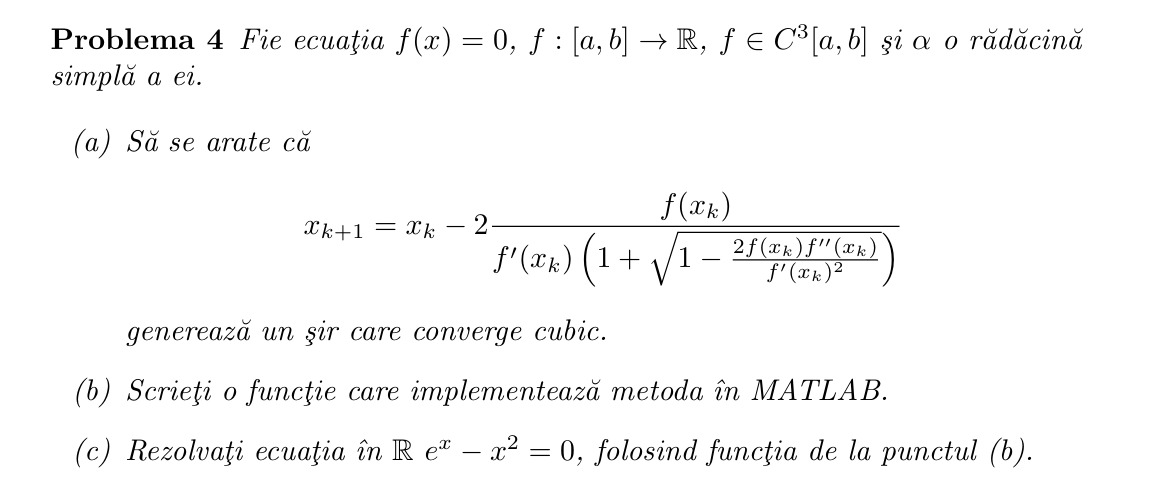

Convergență cubică -: ordinul de convergență p=3. Pentru a se îndeplini asta trebuie ca f(alfa) =0, pfi'(alfa)=0, phi''(alfa)=0 si phi'''(alfa)!=0.

syms x alpha lambda f(x) h(x)
phi = x - 2*f(x)/(diff(f(x),x,1)* (1+ sqrt(1- 2*f(x)*diff(f(x),x,2)/diff(f(x),x,1)^2)))

$$phi = x-\frac{2\,f\left(x\right)}{\left(\sqrt{1-\frac{2\,f\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)}{{\left(\frac{\partial }{\partial x}f\left(x\right)\right)}^{2}}}+1\right)\,\frac{\partial }{\partial x}f\left(x\right)}$$

phi_df1 = diff(phi, 1);
phi_df1 = subs(phi_df1, diff(f, 1), diff(h, 1));
phi_df1 = subs(phi_df1, diff(f, 2), diff(h, 2));
phi_df1 = subs(phi_df1, diff(f, 3), diff(h, 3));
phi_df1 = subs(phi_df1, f, 0)

$$phi\_df1 = 0$$


phi_df2 = diff(phi, 2);
phi_df2 = subs(phi_df2, diff(f, 1), diff(h, 1));
phi_df2 = subs(phi_df2, diff(f, 2), diff(h, 2));
phi_df2 = subs(phi_df2, diff(f, 3), diff(h, 3));
phi_df2 = subs(phi_df2, diff(f, 4), diff(h, 4));
phi_df2 = simplify(subs(phi_df2, f, 0))

$$phi\_df2 = 0$$


phi_df3 = diff(phi, 3);
phi_df3 = subs(phi_df3, diff(f, 1), diff(h, 1));
phi_df3 = subs(phi_df3, diff(f, 2), diff(h, 2));
phi_df3 = subs(phi_df3, diff(f, 3), diff(h, 3));
phi_df3 = subs(phi_df3, diff(f, 4), diff(h, 4));
phi_df3 = subs(phi_df3, diff(f, 5), diff(h, 5));
phi_df3 = simplify(subs(phi_df3, f, 0))

$$phi\_df3 = -\frac{\frac{\partial^{3}}{\partial x^{3}}h\left(x\right)}{\frac{\partial }{\partial x}h\left(x\right)}$$


syms x

f = @(x) exp(x) - x^2;

x_true = eval(solve(f(x)==0));
x_true = x_true(2)

x_true = -0.7035

fd = diff(f, x, 1)

$$fd = {\mathrm{e}}^{x}-2\,x$$

fd2 = diff(f, x, 2)

$$fd2 = {\mathrm{e}}^{x}-2$$


[x_aprox, i] = ModifiedNewton(f, fd, fd2, -1, 1e-8, 1e-8,100);
x_aprox = eval(x_aprox)

x_aprox = -0.7035


rest = abs(x_aprox - x_true)

rest = 0







%SAU
syms x alpha lambda f(x) h(x)
f(x)=exp(x)-x^2

$$f(x) = {\mathrm{e}}^{x}-x^{2}$$

phi = x-2*f(x)/(diff(f,x)*(1+sqrt(1-2*f(x)*diff(f,x,2)/diff(f,x)^2)))

$$phi(x) = x+\frac{2\,{\mathrm{e}}^{x}-2\,x^{2}}{\left(\sqrt{1-\frac{\left({\mathrm{e}}^{x}-2\right)\,\left(2\,{\mathrm{e}}^{x}-2\,x^{2}\right)}{{\left(2\,x-{\mathrm{e}}^{x}\right)}^{2}}}+1\right)\,\left(2\,x-{\mathrm{e}}^{x}\right)}$$

[z,ni]=mas(phi,-1,1e-8,1e-8,20);
aproximarea_radacinii=eval(z)

aproximarea_radacinii = -0.7035

numarul_iteratiilor_necesare=ni 

numarul_iteratiilor_necesare = 3

function rest = RR(f, a1, a2, a3, a4, t3, t4)
    % Define the symbolic variable
    syms t

    % Calculate the integral part of the rest
    rest = int(f(t), t, -1, 1) - a1*subs(f(t), t, -1) - a2*subs(diff(f(t), t), t, -1) - a3*f(t3) - a4*f(t4);
end

.

%[aproximarea_radacinii,nr_iteratii]
function [z,ni]=ModifiedNewton(f, fd, fd2, x0,ea,er,nmax)
if nargin < 6, nmax=50; end
if nargin < 5, er=0; end
if nargin < 4, ea=1e-3; end
xp=x0(:);
for k=1:nmax
    %xc=xp-fd(xp)\f(xp); %disp(xc);
    xc=xp - 2*f(xp)/(subs(fd,xp)* (1+ sqrt(1- 2*f(xp)*subs(fd2,xp)/subs(fd,xp)^2)));
    if norm(xc-xp,inf)<ea+er*norm(xc,inf)
        z=xc; %succes
        ni=k;
        return
    end
    xp=xc;
end
error('S-a depasit numarul maxim de iteratii');
end

.

function [z,ni] = mas( f, x0, ea, er, nmax )
% MAS - Metoda aproximatiilor succesive pentru ecuatii in R
% apel [z,ni] = mas( f, x0, ea, er, nmax )
if nargin<5, nmax=100; end
if nargin<4, er=0; end
if nargin<3, ea=1e-4; end
for i=1:nmax
  x1=f(x0);
  delta=eval(abs(x0-x1));
  if delta<ea || delta<er*abs(x1)
      z=x1; ni=i;
      return
  end
  x0=x1;
end
error('iteration number exceeded')
end